## **Additional piping and fitting**

In the previous sections [ColdPlate](matlab:open('.\ColdPlate.mlx')) and [Radiator](matlab:open('.\Radiator.mlx')), we have already determined expected pressure losses at nominal conditions for those components. Adding to that will be additional pressure lossed for piping and fittings. Similar as it is done in the Simscape components, we will determine length of piping and the aggregarted equivalent length of additional fittings.

**Todo: Add calculations for additional length**

#### Determine pressure drop for additional piping

pipingD         = 10; % mm
pipingLength    = 2;  % m
pipingAddLength = 1; % m
pipingArea      = pi*(pipingD/2)^2; % mm^2
pipingRoughness = 15e-6;       % m

Determine pressure loss in Simscape model

open_system("example_Piping")

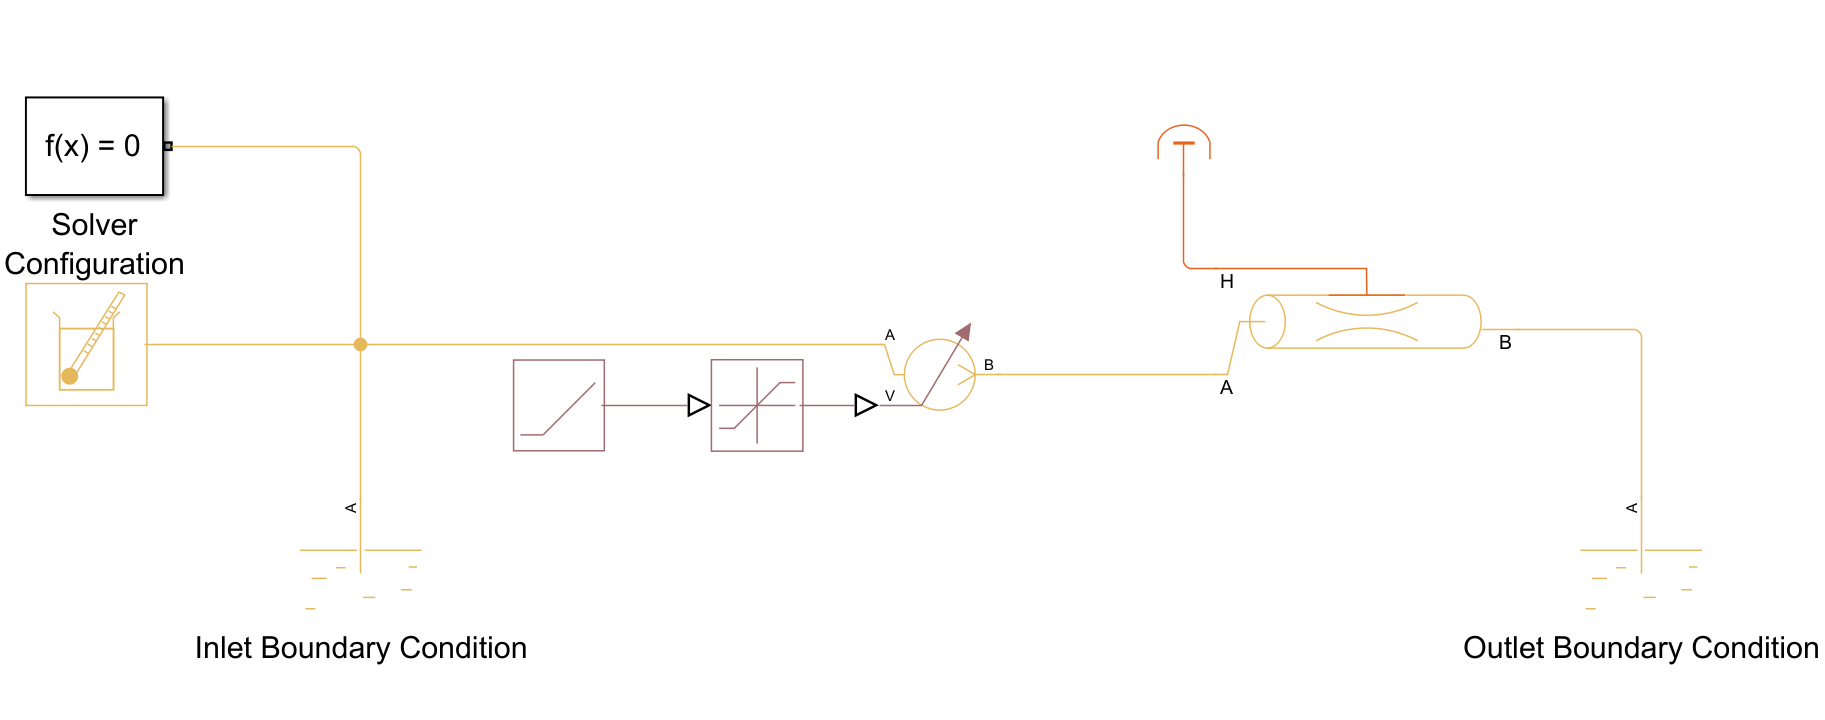

Again, we are using a Pipe (TL) block to represent the additional piping and fitting elements. The pipe geometry is parameterized the above values. As in previous models we set the cross-sectional areas of connected ports to similar values. Here, this is chosen to be the piping cross-sectional area. 

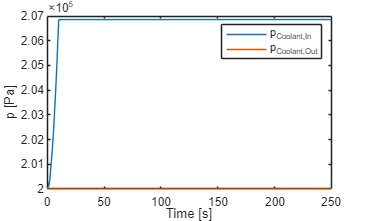

simInp = Simulink.SimulationInput("example_Piping");
simInp = simInp.setModelParameter("StopTime","250");

simOut = sim(simInp);

pPipingIn       = simOut.simlog.Pipe_TL.A.p.series.values('Pa');
pPipingOut      = simOut.simlog.Pipe_TL.B.p.series.values('Pa');

dpPiping        = pPipingIn-pPipingOut;

figure
plot(simOut.tout,[pPipingIn,pPipingOut])
ylabel('p [Pa]')
xlabel('Time [s]')
legend('p_{Coolant,In}','p_{Coolant,Out}')
hold off


disp(dpPiping(end))

   6.8563e+03



#### Pump parameterization

The overall pressure drop determined for the cold plate (in [ColdPlate](matlab:open('.\ColdPlate.mlx'))), the raditor (in [Radiator](matlab:open('.\Radiator.mlx'))) and the additional piping gives a overall pressure loss of rougly 1.55 bars. The system will be using a centrifugal pump. The suitable Simscape Fluids component [Centrifugal Pump (TL)](https://www.mathworks.com/help/releases/R2025a/hydro/ref/centrifugalpumptl.html) offers different paramaterization options. Since we are not working with a specific vendor data sheet, we will use the *Capacity, head, and breake power and reference shaft speed* which uses an analytical model.This requires the nominal capacity, nominal head and nominal break power as well as maximum head at zero capacity and maximum capacity at zero head. 

Determine head with nominal flow rate

dpReq        = 1.55e5;  % (Pa) required pressure difference 
pumpHeadCalc = dpReq/rhoCoolant/9.81

pumpHeadCalc = 15.8456

Brake power at reference point

pumpEff        = 0.6;
pumpBreakCalc = rhoCoolant*9.81*VDot*pumpHeadCalc/pumpEff

pumpBreakCalc = 24.7875

Using a commong quadratic head-flow curve for a centrifugal pump and picking a point of best efficiency at ~60%, we determine the remaining parameters maximum head at zero capacity and maximum capacity at zero head:

pumpCapZeroHeadCalc = VDotLPM/0.6

pumpCapZeroHeadCalc = 9.5952

pumpHeadRefMaxCalc = pumpHeadCalc/(1-0.6^2)

pumpHeadRefMaxCalc = 24.7587

We will use rounded values for the Simscape model and select a pump reference speed of 2900 rpm and a pump inertia value of 1e-5 kg*m^2. 

pumpHead        = 16;   % m
pumpBrkPwr      = 26;   % W
pumpHeadRefMax  = 24;   % m
pumpCapZeroHead = 10;   % lpm
pumpRefSpeed    = 2900; % rpm
pumpInertia     = 1e-5; % kg*m^2

Test pump in Simscape model

open_system("example_Pump")

The test model uses a Pressure Source (TL) block to mimick a load, we use an Inport block connected to that to load a test vector into the model. To test the pump range, we ramp up the load beyond the expected maximum pressure drop. You can also validate the pump curve with the current paramterization by right-clicking the pump component and selecting *Fluids->Plot Pump Characteristics:*

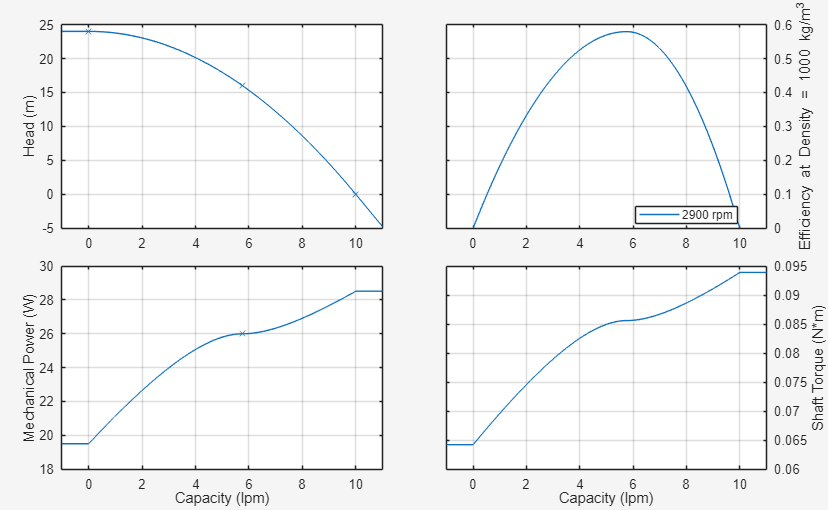

Note that there is also an Inertia component connected to the mechanical R port of the pump. It is good practice to add an inertia (or compliance) to avoid instablities with instantaneous changes.  

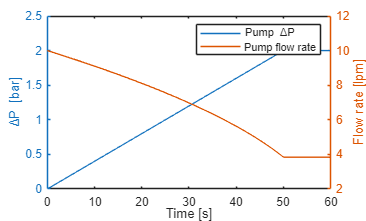

tInPumpTest     = [0;50;60];  % s
loadInPumpTest  = [0;2.0;2.0]; % bar

simInp = Simulink.SimulationInput('example_Pump');
simOut = sim(simInp);

pDiffPump = simOut.simlog.Centrifugal_Pump_TL.p_diff.series.values('bar');
VDotPump  = simOut.simlog.Centrifugal_Pump_TL.q_A.series.values('lpm');
effPump = simOut.simlog.Centrifugal_Pump_TL.efficiency.series.values;

figure
yyaxis left
plot(simOut.tout,pDiffPump);
ylabel('\DeltaP [bar]')
yyaxis right
plot(simOut.tout,VDotPump);
ylabel('Flow rate [lpm]')
xlabel('Time [s]')
legend('Pump \DeltaP','Pump flow rate')
hold off

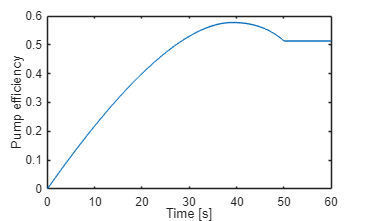

figure
plot(simOut.tout,effPump);
ylabel('Pump efficiency')
xlabel('Time [s]')

We see hast the pressure difference is ramping up as the flow rate is increasing, the pump efficiency represents well what we saw previously in the pump curve. 